# EngineFaultDB: Automotive Engine Fault Classification

## Data Preparation

clc; clear; close all;

Data_location = "../Datasets/EngineFaultDB_Final.xlsx";
data = readtable(Data_location, 'VariableNamingRule', 'preserve');

data.Properties

ans =   TableProperties - 속성 있음:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Fault'  'MAP'  'TPS'  'Force'  'Power'  'RPM'  'Consumption L/H'  'Consumption L/100KM'  'Speed'  'CO'  'HC'  'CO2'  'O2'  'Lambda'  'AFR'}
           VariableTypes: ["double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"]
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: 사용자 지정 속성을 설정하지 않았습니다.
 addprop 및 rmprop을(를) 사용하여 CustomProperties를 수정하십시오.


% Sampling Freq
fs = 10;

## Time Domain Anaylsis

### MAP

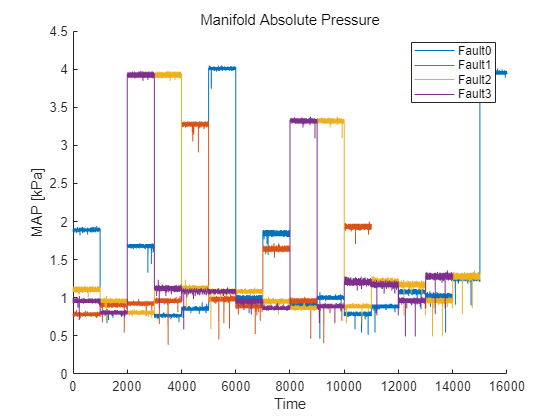

% Data Length Configuration
L0 = height(find(data.Fault == 0)); % Fault 0 : 16,000
L1 = height(find(data.Fault == 1)); % Fault 1 : 10,988
L2 = height(find(data.Fault == 2)); % Fault 2 : 15,000
L3 = height(find(data.Fault == 3)); % Fault 3 : 14,001

data_fault0 = data(data.Fault == 0, :);
data_fault1 = data(data.Fault == 1, :);
data_fault2 = data(data.Fault == 2, :);
data_fault3 = data(data.Fault == 3, :);

figure;
hold on;
plot((1:L0), data_fault0.TPS);
plot((1:L1), data_fault1.TPS);
plot((1:L2), data_fault2.TPS);
plot((1:L3), data_fault3.TPS);
legend('Fault0', 'Fault1', 'Fault2', 'Fault3')
xlabel("Time");
ylabel("MAP [kPa]");
title("Manifold Absolute Pressure");

% MAP, Force, Power, CO, HC has too much outliers
correlated_vars = [2; 4; 5; 10; 11];

data(:, correlated_vars) = [];

## Correlation Check

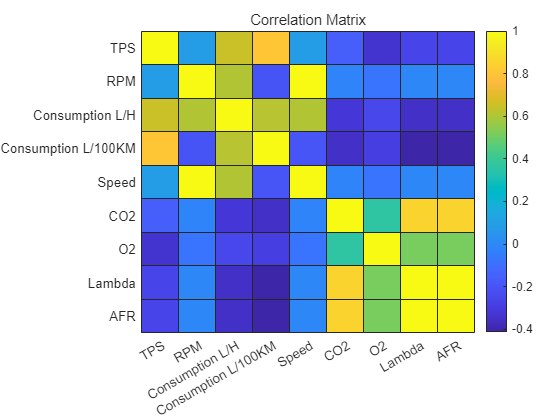

figure;
variable_names = data.Properties.VariableNames(2:end);
corr_matrix = corrcoef(table2array(data(:, 2:end)));
heatmap(corr_matrix, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Correlation Matrix', 'Colormap', parula);

disp(corr_matrix);

    1.0000    0.0929    0.6478    0.8069    0.0927   -0.1640   -0.3308   -0.2612   -0.2612
    0.0929    1.0000    0.6035   -0.1977    0.9969   -0.0159   -0.0800   -0.0046   -0.0045
    0.6478    0.6035    1.0000    0.6141    0.6033   -0.3134   -0.2518   -0.3476   -0.3475
    0.8069   -0.1977    0.6141    1.0000   -0.1972   -0.3498   -0.2904   -0.4127   -0.4127
    0.0927    0.9969    0.6033   -0.1972    1.0000   -0.0162   -0.0809   -0.0052   -0.0052
   -0.1640   -0.0159   -0.3134   -0.3498   -0.0162    1.0000    0.3604    0.8526    0.8526
   -0.3308   -0.0800   -0.2518   -0.2904   -0.0809    0.3604    1.0000    0.5198    0.5198
   -0.2612   -0.0046   -0.3476   -0.4127   -0.0052    0.8526    0.5198    1.0000    1.0000
   -0.2612   -0.0045   -0.3475   -0.4127   -0.0052    0.8526    0.5198    1.0000    1.0000



### 연관성 높은 Variables 제거

corr_threshold = 0.8;
high_corr = abs(corr_matrix) > corr_threshold

high_corr = 9×9 logical 배열
   1   0   0   1   0   0   0   0   0
   0   1   0   0   1   0   0   0   0
   0   0   1   0   0   0   0   0   0
   1   0   0   1   0   0   0   0   0
   0   1   0   0   1   0   0   0   0
   0   0   0   0   0   1   0   1   1
   0   0   0   0   0   0   1   0   0
   0   0   0   0   0   1   0   1   1
   0   0   0   0   0   1   0   1   1


high_corr = high_corr - eye(size(high_corr));
[rows, cols] = find(high_corr);

correlated_vars = unique(max(rows, cols));
variable_names = data.Properties.VariableNames(2:end);
vars_to_remove = variable_names(correlated_vars);

disp(['Removed variables: ', strjoin(vars_to_remove, ', ')]);

Removed variables: Consumption L/100KM, Speed, Lambda, AFR


data(:, correlated_vars+1)=[];
% update
data_fault0 = data(data.Fault == 0, :);
data_fault1 = data(data.Fault == 1, :);
data_fault2 = data(data.Fault == 2, :);
data_fault3 = data(data.Fault == 3, :);

### MAP - Segmentation (1:1000)

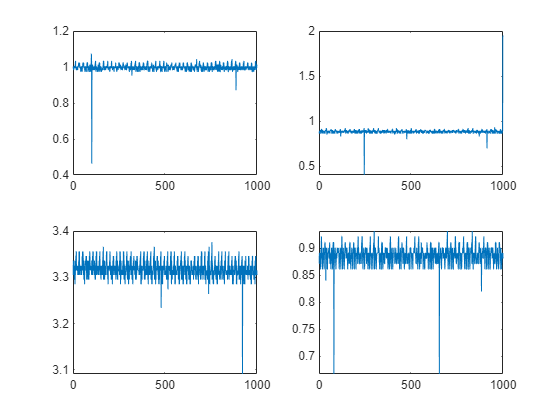

figure;
t = 10000;
subplot(2,2,1);
plot(1:1000, data_fault0.TPS(t-999:t, :));
subplot(2,2,2);
plot(1:1000, data_fault1.TPS(t-999:t, :));
subplot(2,2,3);
plot(1:1000, data_fault2.TPS(t-999:t, :));
subplot(2,2,4);
plot(1:1000, data_fault3.TPS(t-999:t, :));

## 노이즈, 이상치 확인 및 제거

Fault1의 데이터셋이 총 10998개까지 있으므로, 1000 개의 Datasets씩, 10000 개의 Datasets들을 처리함.

9001 이후의 Datasets이 정상적이지 않음.

### TPS

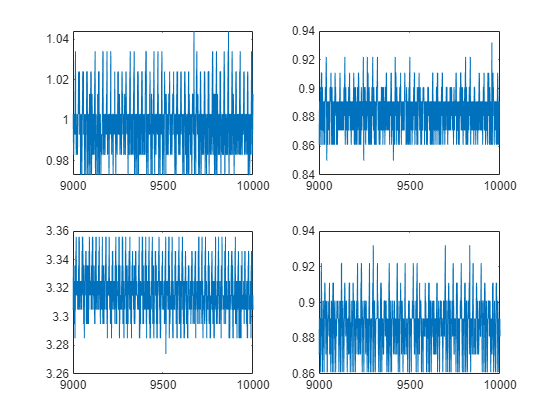

data_fault = {data_fault0, data_fault1, data_fault2, data_fault3};
for i = 1:4
    for t = 1000:1000:10000
        outliers = isoutlier(data_fault{i}(t-999:t, :));
        data_fault{i}(t-999:t, :) = filloutliers(data_fault{i}(t-999:t, :), 'linear');
    end
end

%update
data_fault0 = data_fault{1};
data_fault1 = data_fault{2};
data_fault2 = data_fault{3};
data_fault3 = data_fault{4};


figure;
subplot(2,2,1);
plot(t-999:t, data_fault0.TPS(t-999:t, :));
subplot(2,2,2);
plot(t-999:t, data_fault1.TPS(t-999:t, :));
subplot(2,2,3);
plot(t-999:t, data_fault2.TPS(t-999:t, :));
subplot(2,2,4);
plot(t-999:t, data_fault3.TPS(t-999:t, :));

### RPM

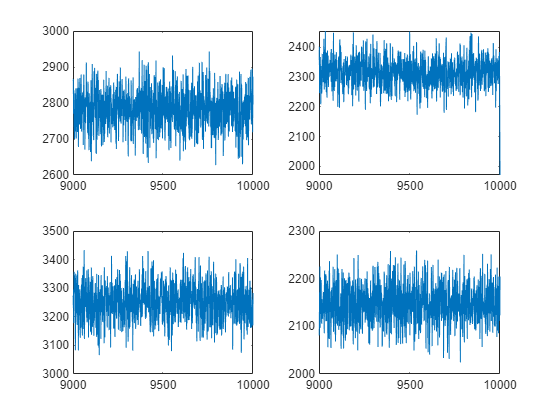

figure;
subplot(2,2,1);
plot(t-999:t, data_fault0.RPM(t-999:t, :));
subplot(2,2,2);
plot(t-999:t, data_fault1.RPM(t-999:t, :));
subplot(2,2,3);
plot(t-999:t, data_fault2.RPM(t-999:t, :));
subplot(2,2,4);
plot(t-999:t, data_fault3.RPM(t-999:t, :));

### Consumption L/H

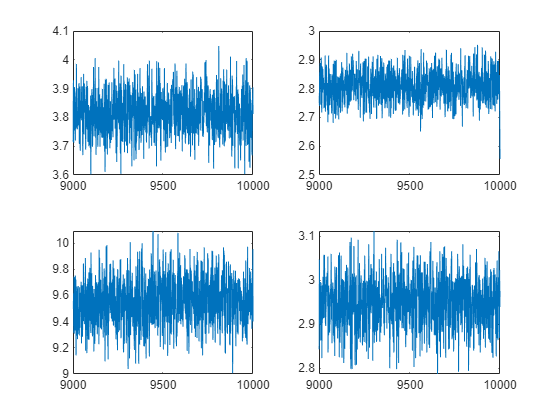

figure;
subplot(2,2,1);
plot(t-999:t, data_fault0.("Consumption L/H")(t-999:t, :));
subplot(2,2,2);
plot(t-999:t, data_fault1.("Consumption L/H")(t-999:t, :));
subplot(2,2,3);
plot(t-999:t, data_fault2.("Consumption L/H")(t-999:t, :));
subplot(2,2,4);
plot(t-999:t, data_fault3.("Consumption L/H")(t-999:t, :));

### CO2

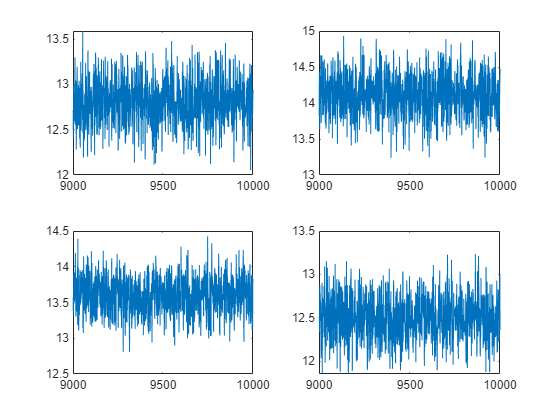

figure;
subplot(2,2,1);
plot(t-999:t, data_fault0.CO2(t-999:t, :));
subplot(2,2,2);
plot(t-999:t, data_fault1.CO2(t-999:t, :));
subplot(2,2,3);
plot(t-999:t, data_fault2.CO2(t-999:t, :));
subplot(2,2,4);
plot(t-999:t, data_fault3.CO2(t-999:t, :));

### O2

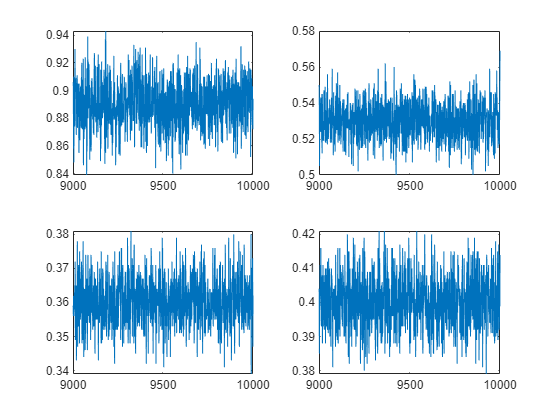

figure;
subplot(2,2,1);
plot(t-999:t, data_fault0.O2(t-999:t, :));
subplot(2,2,2);
plot(t-999:t, data_fault1.O2(t-999:t, :));
subplot(2,2,3);
plot(t-999:t, data_fault2.O2(t-999:t, :));
subplot(2,2,4);
plot(t-999:t, data_fault3.O2(t-999:t, :));

## Feature Extraction - Time Domain Features

addpath("../../../Library");

k = 1;
t0_feature = table;
for i = 1000:1000:10000
    features = timeFeatures(data_fault0.RPM(i-999:i, :));
    t0_feature = [t0_feature; features];
    k = k+1;
end

% for i = 1000:1000:10000
%     features = timeFeatures(data_fault0.TPS(i-999:i, :));
%     t0_feature = [t0_feature; features];
%     k = k+1;
% end

% features_time = {t0_feature, t1_feature, t2_feature, t3_feature};

X_train = table2array(t0_feature);
Y_train = t0_feature.Properties.VariableNames;
mdl_svm = fitcecoc(X_train, Y_train, 'ClassNames',{'normal','inner','outer'})
% mlResubErr_svm = resubLoss(mdl_svm)

% f0_MAP = rescale(data_fault0.MAP);
% f1_MAP = rescale(data_fault1.MAP);
% f2_MAP = rescale(data_fault2.MAP);
% f3_MAP = rescale(data_fault3.MAP);
% 
% figure;
% hold on;
% plot(1:2000, f0_MAP(1:2000, :));
% plot(1:2000, f1_MAP(1:2000, :));
% plot(1:2000, f2_MAP(1:2000, :));
% plot(1:2000, f3_MAP(1:2000, :));
% legend("f0", "f1", "f2", "f3");


% figure();
% t = 1:16000;
% Force = table2array(data(1:16000, 4));
% Power = table2array(data(1:16000, 5));
% Speed = table2array(data(1:16000, 9));
% 
% hold on;
% subplot(3,1,1);
% plot(t, Force);
% title("Force - Healthy Engine");
% ylabel("N");
% xlabel("sampling time");
% legend("Force")
% 
% subplot(3,1,2);
% plot(t, Power);
% title("Power - Healthy Engine");
% ylabel("Nm");
% xlabel("sampling time");
% legend("Power")
% 
% subplot(3,1,3);
% plot(t, Speed);
% title("Speed - Healthy Engine");
% ylabel("m/s");
% xlabel("sampling time");
% legend("Speed")
% 
% hold off;

% t_2=1:2000;
% RPM_fault1 = table2array(data(16001:16001+1999, 6));
% plot(t_2,RPM_fault1);